clearvars
close all
clc

#### read the WAVE file (*.wav)

% Fp sampling frequency in Hz
[y, Fp] = audioread('hw1_peter_and_the_wolf_2.wav');
% so that the samplig period is
T = 1/Fp; % [s]
Ny = length(y); % length

sound(y,Fp);
pause(Ny/Fp);

#### show the ORIGINAL signal in time and frequency

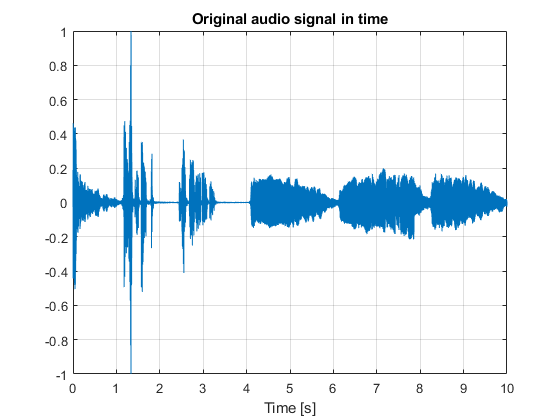

ty = T*(0:Ny-1); % time samples
Y = T*fft(y); % fft
fy = (0:Ny-1)/(T*Ny); % frequency samples
plot(ty,y); 
grid; 
xlabel('Time [s]'); 
title('Original audio signal in time');

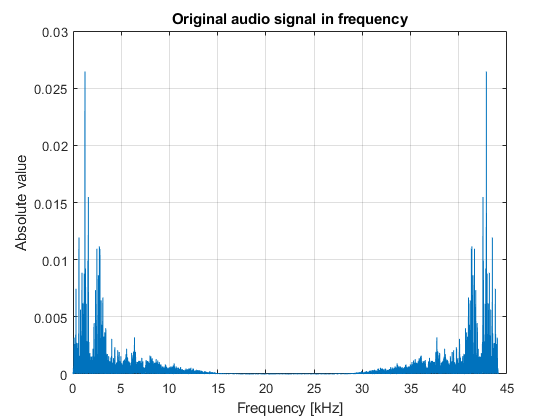

plot(fy/1e3,abs(Y)); 
grid;
xlabel('Frequency [kHz]'); 
ylabel("Absolute value");
title('Original audio signal in frequency');

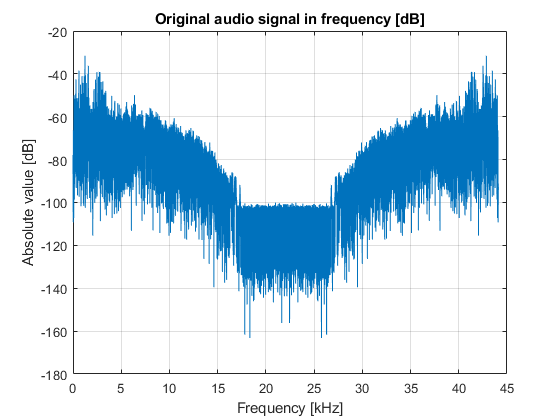

plot(fy/1e3,20*log10(abs(Y))); 
grid;
xlabel('Frequency [kHz]'); 
ylabel("Absolute value [dB]");
title('Original audio signal in frequency [dB]');

#### Analog reference filter: $H_a \left(s\right)=\frac{\left(1+i\;2\pi f\;\mathrm{T2}\right)}{\left(1+i\;2\pi f\;\mathrm{T1}\right)\left(1+i\;2\pi f\;\mathrm{T3}\right)}$

T1 = 75e-6; % [s]
T2 = 318e-6; % [s]
T3 = 3180e-6; % [s]

#### Reference frequency response $H_{\mathrm{ref}} \left(f\right)=H_a \left(i\;\;\mathrm{tg}\left(\pi \;f\;T\right)\left(\frac{2}{T}\right)\right)$

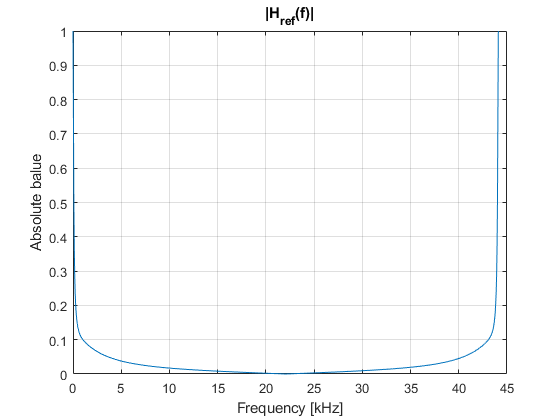

f = 0:Fp/1000:Fp;  %% frq. vector
num_ref = ( 1 + T2*1i*tan(pi*f*T)*(2/T) );
den_ref = ( 1 + T1*1i*tan(pi*f*T)*(2/T) ) .*( 1 + T3*1i*tan(pi*f*T)*(2/T) );
H_ref=num_ref./den_ref;
plot(f/1e3,abs(H_ref));
grid;
xlabel("Frequency [kHz]");
ylabel("Absolute balue");
title("|H_{ref}(f)|");

#### poles and zeros of the filter in the z-domain, $s=\frac{2}{T}\frac{1-z^{-1} }{1+z^{-1} }$

z1 = ( 2 - T/T2 ) / ( 2 + T/T2 );
z2 = -1;
p1 = ( 2 - T/T1 ) / ( 2 + T/T1 );
p2 = ( 2 - T/T3 ) / ( 2 + T/T3 );

% normalization factor
K = ( (1-p1)*(1-p2) ) / ( 2*(1-z1) ) ; 


#### builds the frequency response

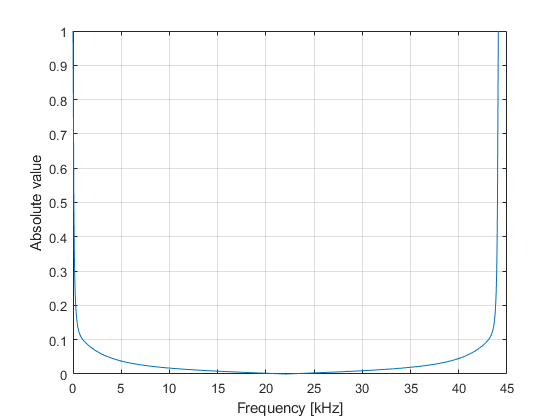

num = ( 1 -z1*exp(-1i*2*pi*f*T) ).*( 1 - z2*exp(-1i*2*pi*f*T) );
den = ( 1 -p1*exp(-1i*2*pi*f*T) ).*( 1 - p2*exp(-1i*2*pi*f*T) );
H = K*(num./den); 
plot(f/1e3,abs(H));
grid;
xlabel("Frequency [kHz]");
ylabel("Absolute value");

title("|H(f)|")


#### show poles and zeros

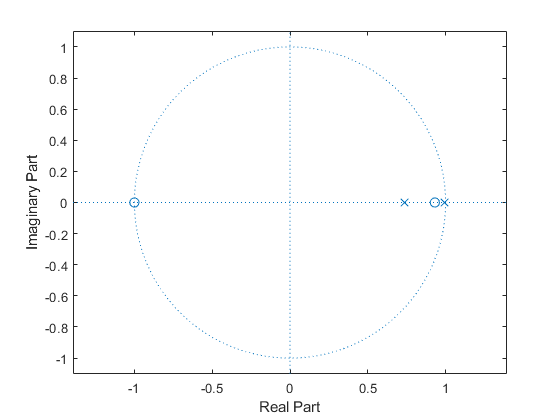

b = K*[1 -z1-z2  z1*z2];
a = [1 -p1-p2 p1*p2];
zplane(b,a);

#### filter the original signal

z = filter(b,a,y);
sound(z, Fp);

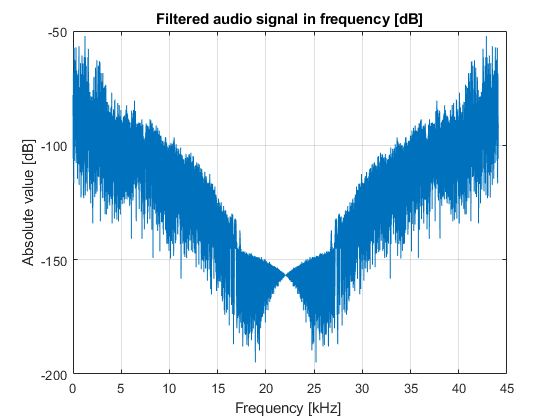

Nz=length(z);
tz=(0:Nz-1)*T;
Z = T*fft(z); 
fz = (0:Nz-1)/(T*Nz); % frequency vector of Z

plot(fz/1e3,20*log10(abs(Z))); grid;
xlabel('Frequency [kHz] '); 
ylabel("Absolute value [dB]");
title('Filtered audio signal in frequency [dB]');

#### ADVANCED - DIRECT OPTIMIZATION

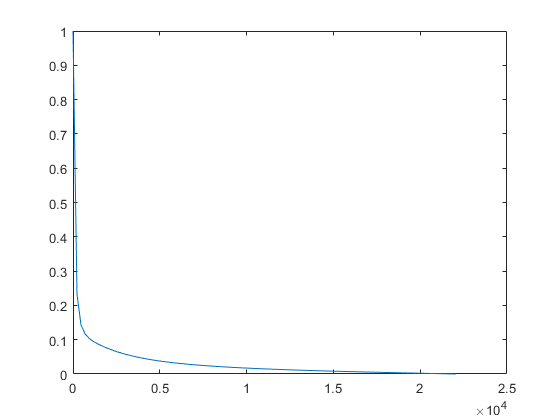

N = 2;

% frequencies samples of interest
F = Fp/(N+1)/64; % min 32 samples per cosine period
f_opt = (0:F:Fp/2).'; % frequency samples, column vector

num_ref = ( 1 + T2*1i*tan(pi*f_opt*T)*(2/T) );
den_ref = ( 1 + T1*1i*tan(pi*f_opt*T)*(2/T) ) .*( 1 + T3*1i*tan(pi*f_opt*T)*(2/T) );
H_ref=num_ref./den_ref;
plot(f_opt,abs(H_ref));


% build matrices
w = ones(size(f_opt,1),1);
d = abs(H_ref); % ideal filter shape 


% run iterative algorithm
[zk,pk] = zero_pole_identification(d,f_opt,w,N,T);

it#1: error = -3.5119 dB
it#2: error = -3.6331 dB
it#3: error = -3.7924 dB
it#4: error = -4.2791 dB
it#5: error = -5.545 dB
it#6: error = -11.0288 dB
it#7: error = -14.1457 dB
it#8: error = -15.1288 dB
it#9: error = -16.0245 dB
it#10: error = -17.6295 dB
it#11: error = -19.9441 dB
it#12: error = -21.6114 dB
it#13: error = -22.8931 dB
it#14: error = -22.9516 dB
it#15: error = -22.9519 dB


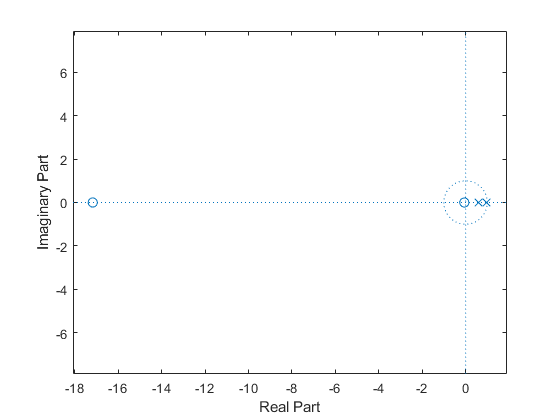



% extracts poles/zeros of interest (may fail in the general case)
pk = pk(abs(pk)<1);
zk = zk([1:4:end,4:4:end]);

% plots poles and zeros
zplane(zk,pk);

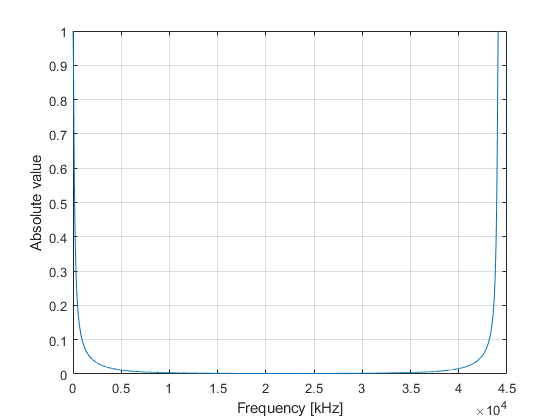


% builds and shows the frequency response
ff = 0:Fp/10000:Fp;  % frequency samples
H_opt = ones(size(ff)); % extracts frequency response (normalized at f=0)
for k = 1:N
    num_opt = (1-zk(k)*exp(-2i*pi*ff*T)) / (1-zk(k)); 
    den_opt = (1-pk(k)*exp(-2i*pi*ff*T)) / (1-pk(k)); 
    H_opt = H_opt.*num_opt./den_opt;
end


% plots the frequency response
plot(ff,abs(H_opt)); grid;
xlabel("Frequency [kHz]");
ylabel("Absolute value");


b_opt = K*[1 -zk(1)-zk(2) zk(1)*zk(2)];
a_opt = [1 -pk(1)-pk(2) pk(1)*pk(2)];


z_opt = filter(b_opt,a_opt,y);
sound(z_opt, Fp);

function [zk,pk] = zero_pole_identification(d,f,w,N,T)
%
% inputs:
% f  : column vector containing the selected frequencies
% d  : column vector containing the target function (squared absolute 
%      value) at frequencies f
% w  : weighting vector (same dimension as f and d)
% N  : ARMA order
% T  : sampling period in the time domain
%
% outputs:
% zk : zeros of the (self-reciprocal) transfer function
% pk : poles of the (self-reciprocal) transfer function
%

V = ones(size(f)); % builds cosines matrix
for n = 1:N
    V = [V,2*cos(2*pi*f*n*T)];
end
wdV = diag(d.*w)*V; % builds product matrices
wV = diag(w)*V;

% starting solution
p_i = poly(0.5*ones(N,1))'; % poles
q_i = [1;zeros(N,1)]; % zeros
Pi = V*p_i; % corresponding numerator
Qi = V*q_i; %           and denominator
delta = max(abs(d-Pi./Qi)); % error

% cycle
for it = 1:100 % set maximum iterations at 100
    
    % vectors for the target function
    g = [zeros(1,2*N+2), 1]; 
    % matrix and vector for inequalities
    A = [ -wV,  wdV-delta*V,  -Qi; ... % absolute bound (upper part)
           wV, -wdV-delta*V,  -Qi; ... % absolute bound (lower part)
           -V,          0*V, 0*Qi; ... % Pi >= 0
          0*V,            V, 0*Qi; ... % Qi <= 1
        ];
    b = [zeros(size(A,1)-size(V,1),1); ones(size(V,1),1)];
    
    % solve the linear program
    options = optimoptions('linprog','Algorithm','interior-point',...
        'Display','off');
    [x,~,exitflag] = linprog(g,A,b,[],[],[],[],[],options); 
    
    % exit criterion
    if (exitflag~=1) % exit if the solver fails
        break
    else
        tmp = max(abs(d-(V*x(1:N+1))./(V*x(N+2:2*N+2)))); % error
        if (tmp/delta>0.999999999) % exit also if the improvement is too small
            break
        else % update your solution
            delta = tmp;
            disp(['it#' num2str(it) ... % you may want to comment this !!!
                  ': error = ' num2str(10*log10(delta)) ' dB'])
            p_i = x(1:N+1);
            q_i = x(N+2:2*N+2);    
            Qi = V*q_i;
        end
    end
end

% extract poles and zeros from the final solution
pk = roots([q_i(end:-1:2); q_i]);
zk = roots([p_i(end:-1:2); p_i]);

end